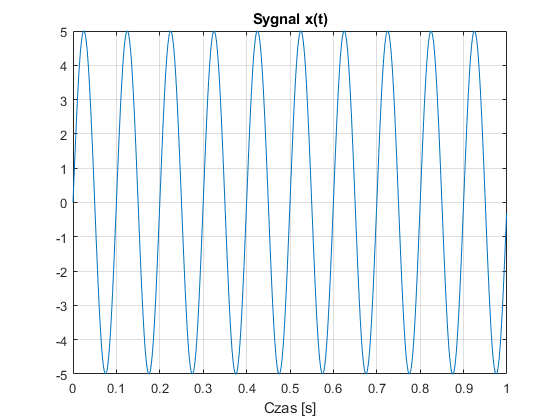

% Skrypt wywolania funkcji wyznaczających parametry sygnalow dyskretnych.
% Funkcje napisane tak aby wykorzystywac podstawowe operacje i petle
%                                           Mateusz Krupnik

% Z przykladu w ksiazce Zielinskiego - w celu porownania wynikow
N=1000; A=5; fx=10; fp=1000;    %parametry sygnalu
A2=7.5; f2=15;
dt = 1/fp;                      %okres probkowania
t = dt*(0:N-1);                 %wektor czasu
x = A*sin(2*pi*fx*t);           %sygnal
y = A2*sin(2*pi*f2*t);
plot(t, x); grid; title('Sygnal x(t)'); xlabel('Czas [s]');

%  Obliczenie parametrow sygnalu - wartosc średnia, maksymalna, minimalna,
%  odchylenie standardowe, energia, moc, wartość skuteczna, wariancja
x_sred = mean(x), x_sred1 = signal_mean(x)

x_sred = -8.4438e-16

x_sred1 = -8.4438e-16

x_max = max(x), x_max = signal_max(x)

x_max = 5

x_max = 5

x_min = min(x), x_min2 = signal_min(x)

x_min = -5

x_min2 = -5

x_std1 = std(x), x_std2 = signal_std(x)

x_std1 = 3.5373

x_std2 = 3.5373

x_eng = dt*sum(x.^2), x_eng2 = signal_energy(x, dt)

x_eng = 12.5000

x_eng2 = 12.5000

x_moc = 1/N * x_eng, x_moc2 = signal_power(x, dt)

x_moc = 0.0125

x_moc2 = 0.0125

x_skut = sqrt(x_moc), x_rms2 = signal_rms(x, dt)

x_skut = 0.1118

x_rms2 = 0.1118

x_var = signal_var(x)

x_var = 12.5125

% Obliczenie momentow normlanych 1, 2, 3 stopnia
x_nor_mom1 = signal_normal_momentum(x, 1), x_nor_mom2 = signal_normal_momentum(x, 2), x_nor_mom3 = signal_normal_momentum(x, 3)

x_nor_mom1 = -7.9551e+04

x_nor_mom2 = -7.9710e+07

x_nor_mom3 = -7.9669e+10

% Obliczenie centralnych momentow normlanych 1, 2, 3 stopnia
x_cen_mom1 = signal_central_momentum(x, 1), x_cen_mom2 = signal_central_momentum(x, 2), x_cen_mom3 = signal_central_momentum(x, 3)

x_cen_mom1 = -7.9551e+04

x_cen_mom2 = -1.2737e+10

x_cen_mom3 = -1.5294e+15

% Obliczenie znormalizowanych momentow normlanych 1, 2, 3 stopnia
x_nor_mon_n1 = signal_normal_momentum_normalized(x, 1), x_nor_mon_n2 = signal_normal_momentum_normalized(x, 2), x_nor_mon_n3 = signal_normal_momentum_normalized(x, 3)

x_nor_mon_n1 = 9.4213e+16

x_nor_mon_n2 = 9.4401e+19

x_nor_mon_n3 = 9.4352e+22

% Obliczenie znormalizowanych centralnych momentow normlanych 1, 2, 3 stopnia
x_cen_mon_n1 = signal_central_momentum_normalized(x, 1), x_cen_mon_n2 = signal_central_momentum_normalized(x, 2), x_cen_mon_n3 = signal_central_momentum_normalized(x, 3)

x_cen_mon_n1 = 5.2052e+16

x_cen_mon_n2 = -1.4706e+34

x_cen_mon_n3 = 2.2157e+51

% Obliczenie środka cieżkości kwadratu sygnalu
x_cwq = signal_cwq(x)

x_cwq = 501.0000

% Oblcizenie wariancji kwadratu sygnalu wokol sredka ciezkosci kwadratu sygnalu
x_vsqacwq_xD = signal_vsqacwq(x)

x_vsqacwq_xD = 8.3207e+04

% Obliczenie szerokości średniokwadratowej
x_rs = signal_rs(x)

x_rs = 288.4557

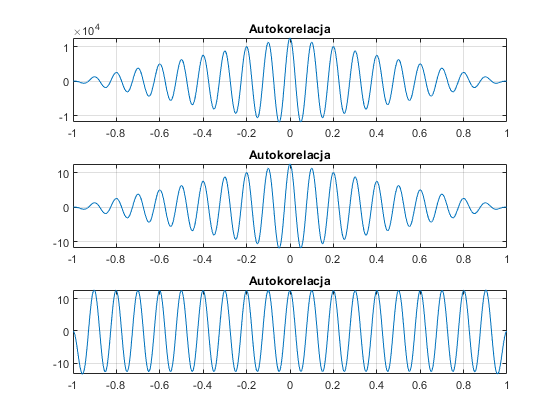

% Obliczenie autokorelacji typu R1, R2 i R3 syganlu
R1 = xcorr(x);              % korelacja nie umormowana
R1_ = signal_corr(x, x, 0); % moja implementacja
R2 = xcorr(x, 'biased');    % unormowana przez dlugosc /N
R2_ = signal_corr(x, x, 1); % moja implementacja
R3 = xcorr(x, 'unbiased');  % unormowana przez /(N-abs(k))
R3_ = signal_corr(x, x, 2); % moja implementacja
tR = [-fliplr(t) t(2:N)]; R = [R1; R2; R3]; R_ = [R1_; R2_; R3_];
% Wykres
figure(1);
for i=1:3
    subplot(3, 1, i);
    plot(tR, R(i, :)); grid; title('Autokorelacja');
end

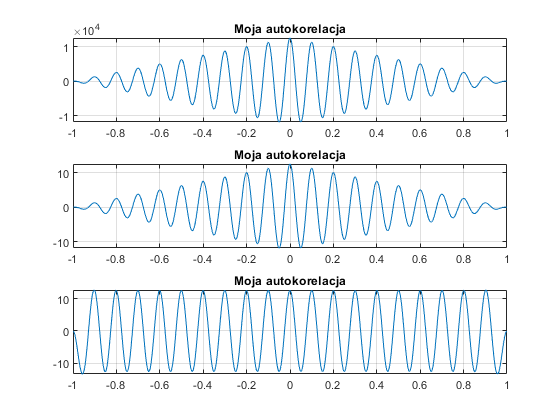


% Wykresy mojej implementacji
figure(2);
for i=1:3
    subplot(3, 1, i);
    plot(tR, R_(i, :)); grid; title('Moja autokorelacja');
end

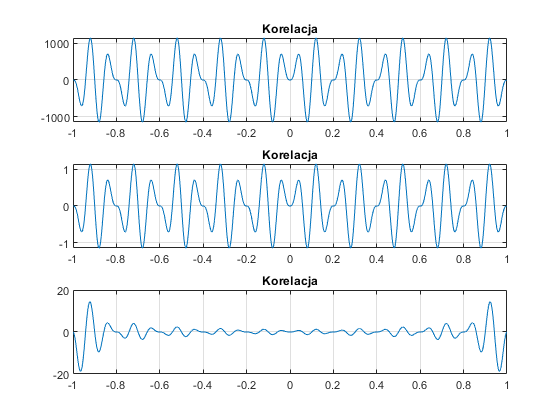


% Obliczenie korelacji wzglednej R1, R2 i R3 syganlu
R1xy = xcorr(x, y);             % korelacja nie umormowana
R1xy_ = signal_corr(x, y, 0);   % moja implementacja 
R2xy = xcorr(x, y, 'biased');   % unormowana przez dlugosc /N
R2xy_ = signal_corr(x, y, 1);   % moja implementacja
R3xy = xcorr(x, y, 'unbiased'); % unormowana przez /(N-abs(k))
R3xy_ = signal_corr(x, y, 2);
tR = [-fliplr(t) t(2:N)]; Rxy = [R1xy; R2xy; R3xy]; Rxy_ = [R1xy_; R2xy_; R3xy_];
% Wykresy
figure(3)
for i=1:3
    subplot(3, 1, i);
    plot(tR, Rxy(i, :)); grid; title('Korelacja');
end

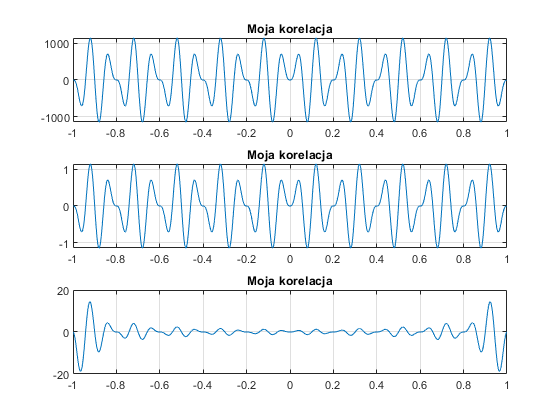


% Wykresy mojej implementacji
figure(4)
for i=1:3
    subplot(3, 1, i);
    plot(tR, Rxy_(i, :)); grid; title('Moja korelacja');
end

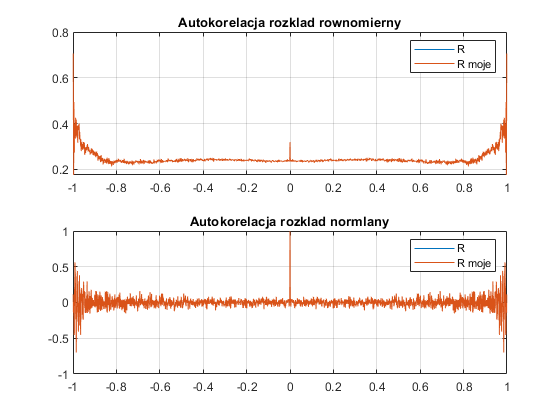

% Test korelacji dla sygnalow pseudolosowych
s1 = rand(1, N); s2=randn(1, N);
R1 = xcorr(s1, 'unbiased'); R2 = xcorr(s2, 'unbiased');     % matlab
R1_ = signal_corr(s1, s1, 2); R2_ = signal_corr(s2, s2, 2); % moja implementacja
% Wykresy korelacji z funkcji xcor i mojej implementacji
figure();
subplot(2,1,1); plot(tR, R1, tR, R1_); legend({'R', 'R moje'}); grid; title('Autokorelacja rozklad rownomierny');
subplot(2,1,2); plot(tR, R2, tR, R2_); legend({'R', 'R moje'}); grid; title('Autokorelacja rozklad normlany');

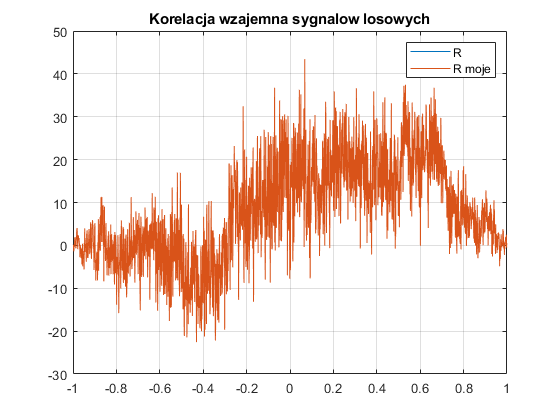

R1xy = xcorr(s1, s2);           % matlab
R1xy_ = signal_corr(s1, s2, 0); % moja implementacja
figure(); plot(tR, R1xy, tR, R1xy_); legend({'R', 'R moje'}); grid; title('Korelacja wzajemna sygnalow losowych');

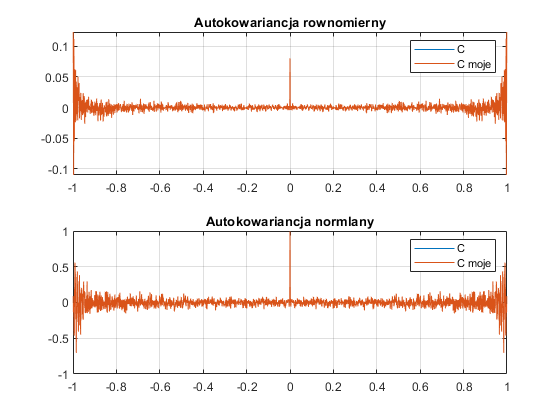

% Kowariancja
C1 = xcov(s1, 'unbiased'); C2 = xcov(s2, 'unbiased');       % matlab
C1_ = signal_cov(s1, s1, 2); C2_ = signal_cov(s2, s2, 2);   % moja implementacja
figure();
subplot(2,1,1); plot(tR, C1, tR, C1_); legend({'C', 'C moje'}); grid; title('Autokowariancja rownomierny');
subplot(2,1,2); plot(tR, C2, tR, C2_); legend({'C', 'C moje'}); grid; title('Autokowariancja normlany');

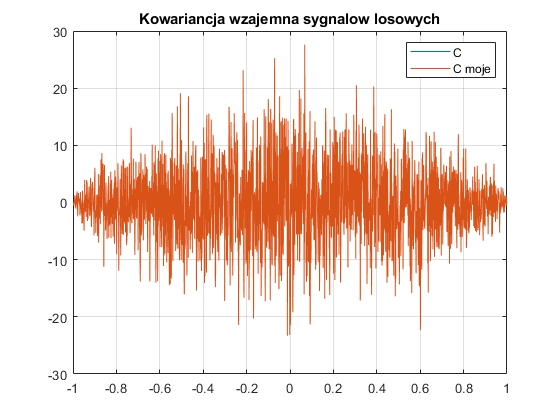

C1xy = xcov(s1, s2);            % matlab
C1xy_ = signal_cov(s1, s2, 0);  % moja implementacja
figure(); plot(tR, C1xy, tR, C1xy_); legend({'C', 'C moje'}); grid; title('Kowariancja wzajemna sygnalow losowych');

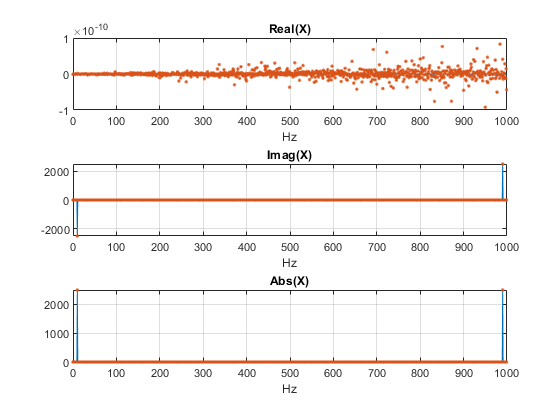

% Obliczenia wspolczynnikow szeregu Fouriera sygnalu

X = fft(x);                 % szybka dyskretna transf Fouriera
X_ = signal_fft(x);         % moja implemetnacja
df = 1/(N*dt);              % czestotliwosc podstawowa f0=df=1/T
f = df * (0:N-1);
figure()
subplot(3,1,1); plot(f, real(X), f, real(X_), '.'); grid; title('Real(X)'); xlabel('Hz');
subplot(3,1,2); plot(f, imag(X), f, imag(X_), '.'); grid; title('Imag(X)'); xlabel('Hz');
subplot(3,1,3); plot(f, abs(X), f, abs(X_), '.'); grid; title('Abs(X)'); xlabel('Hz');

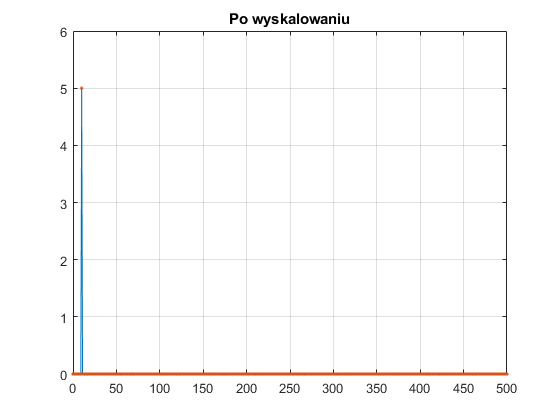

figure();
plot(f(1:N/2+1), abs(X(1:N/2+1))/(N/2), f(1:N/2+1), abs(X_(1:N/2+1))/(N/2), '.'); grid; title('Po wyskalowaniu');

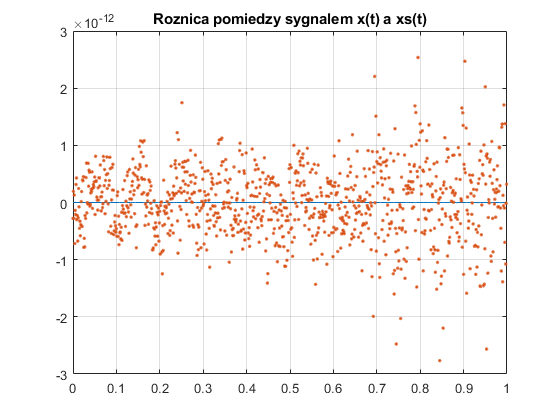

% Synteza sygnalu na podstawie wspolczynnikow szeregu i porownanie z
% orgnalnym przebiegiem
xs = ifft(X);           % matlab
xs_ = signal_ifft(X_);  % moja implementacja
figure();
plot(t, real(x-xs), t, real(x-xs_), '.'); grid; title('Roznica pomiedzy sygnalem x(t) a xs(t)');